# BER in the BPSK system 

Note: Baseband signals are used

%------------------------------------------------------------
clear all; close all; %#ok<CLALL>
% clear previous data and close windows
%------------------------------------------------------------
% Configure Input parameters:
fprintf("\nInput parameters:\n")


Input parameters:


% 1 - num of data bits to transfer through the channel: 
num_ch_bits = [...
    5*10^3, ...
    1*10^4, ...
    5*10^4, ...
    1*10^5, ...
    5*10^5, ...
    1*10^6, ...
    5*10^6, ...
    1*10^7];
fprintf(['Num of data bits to transfer through the channel =' ...
    repmat(' %g',1,numel(num_ch_bits))], num_ch_bits)

Num of data bits to transfer through the channel = 5000 10000 50000 100000 500000 1e+06 5e+06 1e+07

fprintf("\n")

% 2 - Signal-to-noise ratio in the channel - determined by AWGN level:
SNR = -4:2:12;
fprintf(['SNR (dB) =' repmat(' %.1f',1,numel(SNR))], SNR)

SNR (dB) = -4.0 -2.0 0.0 2.0 4.0 6.0 8.0 10.0 12.0

fprintf("\n")

## BITS LOOP - repeats the simulation for each element of num_ch_bits array

BER_dB_all = zeros(length(num_ch_bits),length(SNR)); % Stores results
for iter1 = 1: 1: length(num_ch_bits) 
    fprintf('\n* BPSK simulation *\n')
    fprintf('Number of bits: %g \n', num_ch_bits(iter1))
    % Generate random data bits for transfer
    % TODO: add input for some standard signaals
    channel_bits = randn(1, num_ch_bits(iter1)) >= 0; 
    % random array of -1 and 1
    % condition >=0 turns this array into a 0 and 1 array
    %------------------------------------------------------------
    % Other data
    A = 1; % Signal amplitude on Connection line
    %------------------------------------------------------------
    % Form signal that's sent through the coded channel
     bpsk_coded_signal = A*(2*channel_bits - 1); 
    % SNR LOOP  - calculates BER for every element of SNR array
    BER = 1:length(SNR); % BER and SNR have equal array lengths
    BER_dB = 1:length(SNR);
    for iter2 = 1: 1: length(SNR) 
    %   for every element of BER array execute 1 iteration of the for loop
    %------------------------------------------------------------
    %   Connection line - adding Gaussian noise:
        EbN0 = 10^(SNR(iter2)/10); % 
        AWGN_sigma = sqrt(1/(EbN0*2));
        AWGN = AWGN_sigma * randn(1, length(bpsk_coded_signal));
        received_signal = bpsk_coded_signal + AWGN;
        % Decider's output
        bpsk_decoded_bits = received_signal >= 0;
    %---------------------------------------------------------------
    %   Received bits with error:
        difference = (channel_bits) - (bpsk_decoded_bits);
    %   Num of errors and received bits in curr. iteration:
        tot_err = sum(abs(difference));
        tot_bits = length(bpsk_coded_signal);
        BER(iter2) = tot_err / tot_bits; % BER for current SNR
        BER_dB(iter2) = log10(BER(iter2)); % BER (dB) for current SNR
        fprintf('BER = %f for SNR = %.1f \n',BER_dB(iter2), SNR(iter2));
    end
    % Store for plot
    BER_dB_all(iter1, :) = BER_dB;
end


* BPSK simulation *


Number of bits: 5000 


BER = -0.723538 for SNR = -4.0 
BER = -0.882066 for SNR = -2.0 
BER = -1.085128 for SNR = 0.0 
BER = -1.443697 for SNR = 2.0 
BER = -1.920819 for SNR = 4.0 
BER = -2.795880 for SNR = 6.0 
BER = -3.397940 for SNR = 8.0 
BER = -Inf for SNR = 10.0 
BER = -Inf for SNR = 12.0 



* BPSK simulation *


Number of bits: 10000 


BER = -0.734475 for SNR = -4.0 
BER = -0.895172 for SNR = -2.0 
BER = -1.113509 for SNR = 0.0 
BER = -1.405607 for SNR = 2.0 
BER = -1.879426 for SNR = 4.0 
BER = -2.698970 for SNR = 6.0 
BER = -4.000000 for SNR = 8.0 
BER = -Inf for SNR = 10.0 
BER = -Inf for SNR = 12.0 



* BPSK simulation *


Number of bits: 50000 


BER = -0.735277 for SNR = -4.0 
BER = -0.884523 for SNR = -2.0 
BER = -1.104025 for SNR = 0.0 
BER = -1.412289 for SNR = 2.0 
BER = -1.925915 for SNR = 4.0 
BER = -2.619789 for SNR = 6.0 
BER = -3.795880 for SNR = 8.0 
BER = -Inf for SNR = 10.0 
BER = -Inf for SNR = 12.0 



* BPSK simulation *


Number of bits: 100000 


BER = -0.734616 for SNR = -4.0 
BER = -0.883459 for SNR = -2.0 
BER = -1.101165 for SNR = 0.0 
BER = -1.431798 for SNR = 2.0 
BER = -1.915424 for SNR = 4.0 
BER = -2.605548 for SNR = 6.0 
BER = -3.568636 for SNR = 8.0 
BER = -5.000000 for SNR = 10.0 
BER = -Inf for SNR = 12.0 



* BPSK simulation *


Number of bits: 500000 


BER = -0.730884 for SNR = -4.0 
BER = -0.885082 for SNR = -2.0 
BER = -1.102934 for SNR = 0.0 
BER = -1.428780 for SNR = 2.0 
BER = -1.896812 for SNR = 4.0 
BER = -2.613323 for SNR = 6.0 
BER = -3.665546 for SNR = 8.0 
BER = -Inf for SNR = 10.0 
BER = -Inf for SNR = 12.0 



* BPSK simulation *


Number of bits: 1e+06 


BER = -0.729689 for SNR = -4.0 
BER = -0.886010 for SNR = -2.0 
BER = -1.103099 for SNR = 0.0 
BER = -1.424881 for SNR = 2.0 
BER = -1.901425 for SNR = 4.0 
BER = -2.616185 for SNR = 6.0 
BER = -3.707744 for SNR = 8.0 
BER = -5.397940 for SNR = 10.0 
BER = -Inf for SNR = 12.0 



* BPSK simulation *


Number of bits: 5e+06 


BER = -0.729170 for SNR = -4.0 
BER = -0.884181 for SNR = -2.0 
BER = -1.104653 for SNR = 0.0 
BER = -1.425915 for SNR = 2.0 
BER = -1.903674 for SNR = 4.0 
BER = -2.624373 for SNR = 6.0 
BER = -3.725380 for SNR = 8.0 
BER = -5.494850 for SNR = 10.0 
BER = -Inf for SNR = 12.0 



* BPSK simulation *


Number of bits: 1e+07 


BER = -0.730299 for SNR = -4.0 
BER = -0.884259 for SNR = -2.0 
BER = -1.103823 for SNR = 0.0 
BER = -1.426298 for SNR = 2.0 
BER = -1.904196 for SNR = 4.0 
BER = -2.627419 for SNR = 6.0 
BER = -3.711527 for SNR = 8.0 
BER = -5.443697 for SNR = 10.0 
BER = -Inf for SNR = 12.0 


## Theoretical BER

BER_theory = 0.5*erfc(sqrt(10.^(SNR/10)));
BER_theory_dB = log10(BER_theory); % Theoretical BER (formula)

## Plot BER vs SNR

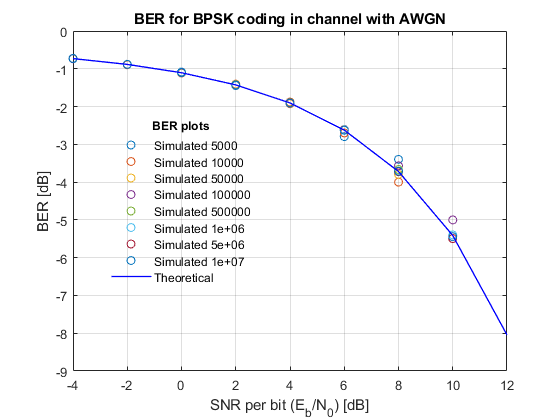

figure('Name','BER vs SNR','NumberTitle','off');
plot(SNR, BER_dB_all, 'o', 'MarkerSize',6);
hold on;  grid on;
plot(SNR, BER_theory_dB, 'b', 'LineWidth',1);
xlabel('SNR per bit (E_b/N_0) [dB]'); ylabel('BER [dB]');
title('BER for BPSK coding in channel with AWGN');
legend_items = strings(1, length(num_ch_bits)+1);
for iter = 1:1:length(num_ch_bits)
    legend_items(iter) = sprintf("Simulated %g",num_ch_bits(iter));
end
legend_items(length(num_ch_bits)+1) = "Theoretical";
lgd = legend(legend_items, 'Location','best');
%lgd = legend(repelem(["Simulated", "Theoretical"], [length(num_ch_bits) 1]), 'Location','best');
legend('boxoff')
title(lgd,'BER plots')